## **Covid Detection Transfer Learning (densenet201)**

## Load Data 

% Data splits provided by the UCSD data github.
imdsTest = imageDatastore(fullfile('COVID19_CT_seg_20cases', 'test'),'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTrain = imageDatastore(fullfile('../ucsd_dataset'),'IncludeSubfolders',true,'LabelSource','foldernames');

## Load Pretrained Network

net = resnet50;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

% analyzeNetwork(net);

net.Layers(1);
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

Extract the layer graph from the traine network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

frozen = 1;
layers(1:frozen) = freezeWeights(layers(1:frozen));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

ACC_array = zeros(0);
FScore_array = zeros(0);


sumTP = 0;
sumFP = 0;
sumTN = 0;
sumFN = 0;

for run = 1:5 %For loop for doing average network performance
    
    run
    
   
%***Image augmentation with variability***%
    % Use an augmented image datastore to automatically resize the training images. 
    % Specify additional augmentation operations to perform on the training images: 
    % randomly flip the training images along the vertical axis and randomly translate them 
    % up to 30 pixels and scale them up to 10% horizontally and vertically. 
    % Data augmentation helps prevent the network from overfitting and memorizing 
    % the exact details of the training images.  
    
    
    pixelRange = [-30 30];
    scaleRange = [0.9 1.1];
    rotRange = [-30 30];
    imageAugmenter = imageDataAugmenter( ...
        'RandXReflection',true, ...
        'RandXTranslation',pixelRange, ...
        'RandYTranslation',pixelRange, ...
        'RandXScale',scaleRange, ...
        'RandYScale',scaleRange, ...
        'RandRotation', rotRange);
    
    augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
        'DataAugmentation',imageAugmenter, 'ColorPreprocessing','gray2rgb');
    

augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");


Specify the training options.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false);

run = 1

run = 2

run = 3

run = 4

run = 5

## Train the network using the training data.

net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Test Images

Classify the test images using the fine-tuned network, and calculate the test accuracy.

[YPred,probs] = classify(net,augimdsTest);

% Get number of images.
numImages = size(YPred,1);
avg_accs = zeros([0,2]);
% Index tracker.
total_idx = 1;
for i = 1:numImages/3
    % Reset sums.
    covidSum = 0;
    noncovidSum = 0;
    % Get the sum of the patient's probability of covid and noncovid
    for j = 1:3
        covidSum = covidSum + probs(total_idx,1);
        noncovidSum = noncovidSum + probs(total_idx,2);
        total_idx = total_idx + 1;
    end
    avg_accs(i,1) = round(covidSum/3,4);
    avg_accs(i,2) = round(noncovidSum/3,4);
end

for i = 1:numImages/3
    % Print patient info and results
    if(i < 10)
        fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
        fprintf('\t\t\t Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
    else
                fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
        fprintf('\t\t\t  Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
    end
end

Patient 1 >> Avg COVID Probability = 0.9982


			 Avg nonCOVID Probability = 0.0018


Patient 2 >> Avg COVID Probability = 0.9927


			 Avg nonCOVID Probability = 0.0073


Patient 3 >> Avg COVID Probability = 0.9980


			 Avg nonCOVID Probability = 0.0020


Patient 4 >> Avg COVID Probability = 0.9852


			 Avg nonCOVID Probability = 0.0148


Patient 5 >> Avg COVID Probability = 0.9952


			 Avg nonCOVID Probability = 0.0048


Patient 6 >> Avg COVID Probability = 0.7413


			 Avg nonCOVID Probability = 0.2587


Patient 7 >> Avg COVID Probability = 0.9966


			 Avg nonCOVID Probability = 0.0034


Patient 8 >> Avg COVID Probability = 0.6238


			 Avg nonCOVID Probability = 0.3762


Patient 9 >> Avg COVID Probability = 0.9582


			 Avg nonCOVID Probability = 0.0418


Patient 10 >> Avg COVID Probability = 0.9514


			  Avg nonCOVID Probability = 0.0486


Patient 11 >> Avg COVID Probability = 0.7027


			  Avg nonCOVID Probability = 0.2973


Patient 12 >> Avg COVID Probability = 0.4866


			  Avg nonCOVID Probability = 0.5134


Patient 13 >> Avg COVID Probability = 0.2713


			  Avg nonCOVID Probability = 0.7287


Patient 14 >> Avg COVID Probability = 0.5580


			  Avg nonCOVID Probability = 0.4420


Patient 15 >> Avg COVID Probability = 0.3028


			  Avg nonCOVID Probability = 0.6972


Patient 16 >> Avg COVID Probability = 0.7212


			  Avg nonCOVID Probability = 0.2788


Patient 17 >> Avg COVID Probability = 0.5431


			  Avg nonCOVID Probability = 0.4569


Patient 18 >> Avg COVID Probability = 0.1786


			  Avg nonCOVID Probability = 0.8214


Patient 19 >> Avg COVID Probability = 0.3596


			  Avg nonCOVID Probability = 0.6404


Patient 20 >> Avg COVID Probability = 0.5540


			  Avg nonCOVID Probability = 0.4460


Patient 1 >> Avg COVID Probability = 1.0000


			 Avg nonCOVID Probability = 0.0000


Patient 2 >> Avg COVID Probability = 1.0000


			 Avg nonCOVID Probability = 0.0000


Patient 3 >> Avg COVID Probability = 0.9999


			 Avg nonCOVID Probability = 0.0001


Patient 4 >> Avg COVID Probability = 0.9964


			 Avg nonCOVID Probability = 0.0036


Patient 5 >> Avg COVID Probability = 0.9999


			 Avg nonCOVID Probability = 0.0001


Patient 6 >> Avg COVID Probability = 0.9999


			 Avg nonCOVID Probability = 0.0001


Patient 7 >> Avg COVID Probability = 1.0000


			 Avg nonCOVID Probability = 0.0000


Patient 8 >> Avg COVID Probability = 0.9904


			 Avg nonCOVID Probability = 0.0096


Patient 9 >> Avg COVID Probability = 0.9795


			 Avg nonCOVID Probability = 0.0205


Patient 10 >> Avg COVID Probability = 1.0000


			  Avg nonCOVID Probability = 0.0000


Patient 11 >> Avg COVID Probability = 0.9182


			  Avg nonCOVID Probability = 0.0818


Patient 12 >> Avg COVID Probability = 0.8555


			  Avg nonCOVID Probability = 0.1445


Patient 13 >> Avg COVID Probability = 0.6068


			  Avg nonCOVID Probability = 0.3932


Patient 14 >> Avg COVID Probability = 0.6851


			  Avg nonCOVID Probability = 0.3149


Patient 15 >> Avg COVID Probability = 0.3891


			  Avg nonCOVID Probability = 0.6109


Patient 16 >> Avg COVID Probability = 0.9895


			  Avg nonCOVID Probability = 0.0105


Patient 17 >> Avg COVID Probability = 0.6129


			  Avg nonCOVID Probability = 0.3871


Patient 18 >> Avg COVID Probability = 0.2457


			  Avg nonCOVID Probability = 0.7543


Patient 19 >> Avg COVID Probability = 0.7134


			  Avg nonCOVID Probability = 0.2866


Patient 20 >> Avg COVID Probability = 0.9024


			  Avg nonCOVID Probability = 0.0976


Patient 1 >> Avg COVID Probability = 0.9993


			 Avg nonCOVID Probability = 0.0007


Patient 2 >> Avg COVID Probability = 0.9998


			 Avg nonCOVID Probability = 0.0002


Patient 3 >> Avg COVID Probability = 0.9997


			 Avg nonCOVID Probability = 0.0003


Patient 4 >> Avg COVID Probability = 0.9994


			 Avg nonCOVID Probability = 0.0006


Patient 5 >> Avg COVID Probability = 0.9995


			 Avg nonCOVID Probability = 0.0005


Patient 6 >> Avg COVID Probability = 0.9817


			 Avg nonCOVID Probability = 0.0183


Patient 7 >> Avg COVID Probability = 0.9996


			 Avg nonCOVID Probability = 0.0004


Patient 8 >> Avg COVID Probability = 0.9226


			 Avg nonCOVID Probability = 0.0774


Patient 9 >> Avg COVID Probability = 0.9914


			 Avg nonCOVID Probability = 0.0086


Patient 10 >> Avg COVID Probability = 0.9992


			  Avg nonCOVID Probability = 0.0008


Patient 11 >> Avg COVID Probability = 0.5173


			  Avg nonCOVID Probability = 0.4827


Patient 12 >> Avg COVID Probability = 0.9384


			  Avg nonCOVID Probability = 0.0616


Patient 13 >> Avg COVID Probability = 0.5536


			  Avg nonCOVID Probability = 0.4464


Patient 14 >> Avg COVID Probability = 0.6234


			  Avg nonCOVID Probability = 0.3766


Patient 15 >> Avg COVID Probability = 0.3645


			  Avg nonCOVID Probability = 0.6355


Patient 16 >> Avg COVID Probability = 0.9588


			  Avg nonCOVID Probability = 0.0412


Patient 17 >> Avg COVID Probability = 0.6190


			  Avg nonCOVID Probability = 0.3810


Patient 18 >> Avg COVID Probability = 0.6354


			  Avg nonCOVID Probability = 0.3646


Patient 19 >> Avg COVID Probability = 0.3896


			  Avg nonCOVID Probability = 0.6104


Patient 20 >> Avg COVID Probability = 0.9256


			  Avg nonCOVID Probability = 0.0744


Patient 1 >> Avg COVID Probability = 0.9999


			 Avg nonCOVID Probability = 0.0001


Patient 2 >> Avg COVID Probability = 0.9998


			 Avg nonCOVID Probability = 0.0002


Patient 3 >> Avg COVID Probability = 0.9997


			 Avg nonCOVID Probability = 0.0003


Patient 4 >> Avg COVID Probability = 0.9761


			 Avg nonCOVID Probability = 0.0239


Patient 5 >> Avg COVID Probability = 0.9992


			 Avg nonCOVID Probability = 0.0008


Patient 6 >> Avg COVID Probability = 0.9549


			 Avg nonCOVID Probability = 0.0451


Patient 7 >> Avg COVID Probability = 0.9883


			 Avg nonCOVID Probability = 0.0117


Patient 8 >> Avg COVID Probability = 0.4903


			 Avg nonCOVID Probability = 0.5097


Patient 9 >> Avg COVID Probability = 0.9244


			 Avg nonCOVID Probability = 0.0756


Patient 10 >> Avg COVID Probability = 0.8197


			  Avg nonCOVID Probability = 0.1803


Patient 11 >> Avg COVID Probability = 0.5124


			  Avg nonCOVID Probability = 0.4876


Patient 12 >> Avg COVID Probability = 0.7175


			  Avg nonCOVID Probability = 0.2825


Patient 13 >> Avg COVID Probability = 0.6439


			  Avg nonCOVID Probability = 0.3561


Patient 14 >> Avg COVID Probability = 0.1675


			  Avg nonCOVID Probability = 0.8325


Patient 15 >> Avg COVID Probability = 0.4416


			  Avg nonCOVID Probability = 0.5584


Patient 16 >> Avg COVID Probability = 0.9753


			  Avg nonCOVID Probability = 0.0247


Patient 17 >> Avg COVID Probability = 0.6139


			  Avg nonCOVID Probability = 0.3861


Patient 18 >> Avg COVID Probability = 0.8784


			  Avg nonCOVID Probability = 0.1216


Patient 19 >> Avg COVID Probability = 0.2002


			  Avg nonCOVID Probability = 0.7998


Patient 20 >> Avg COVID Probability = 0.4267


			  Avg nonCOVID Probability = 0.5733


Patient 1 >> Avg COVID Probability = 0.9979


			 Avg nonCOVID Probability = 0.0021


Patient 2 >> Avg COVID Probability = 0.9968


			 Avg nonCOVID Probability = 0.0032


Patient 3 >> Avg COVID Probability = 0.9982


			 Avg nonCOVID Probability = 0.0018


Patient 4 >> Avg COVID Probability = 0.9972


			 Avg nonCOVID Probability = 0.0028


Patient 5 >> Avg COVID Probability = 0.9933


			 Avg nonCOVID Probability = 0.0067


Patient 6 >> Avg COVID Probability = 0.9381


			 Avg nonCOVID Probability = 0.0619


Patient 7 >> Avg COVID Probability = 0.9988


			 Avg nonCOVID Probability = 0.0012


Patient 8 >> Avg COVID Probability = 0.9814


			 Avg nonCOVID Probability = 0.0186


Patient 9 >> Avg COVID Probability = 0.9868


			 Avg nonCOVID Probability = 0.0132


Patient 10 >> Avg COVID Probability = 0.9998


			  Avg nonCOVID Probability = 0.0002


Patient 11 >> Avg COVID Probability = 0.9287


			  Avg nonCOVID Probability = 0.0713


Patient 12 >> Avg COVID Probability = 0.8992


			  Avg nonCOVID Probability = 0.1008


Patient 13 >> Avg COVID Probability = 0.7759


			  Avg nonCOVID Probability = 0.2241


Patient 14 >> Avg COVID Probability = 0.9512


			  Avg nonCOVID Probability = 0.0488


Patient 15 >> Avg COVID Probability = 0.8372


			  Avg nonCOVID Probability = 0.1628


Patient 16 >> Avg COVID Probability = 0.9947


			  Avg nonCOVID Probability = 0.0053


Patient 17 >> Avg COVID Probability = 0.7257


			  Avg nonCOVID Probability = 0.2743


Patient 18 >> Avg COVID Probability = 0.9221


			  Avg nonCOVID Probability = 0.0779


Patient 19 >> Avg COVID Probability = 0.7809


			  Avg nonCOVID Probability = 0.2191


Patient 20 >> Avg COVID Probability = 0.6387


			  Avg nonCOVID Probability = 0.3613


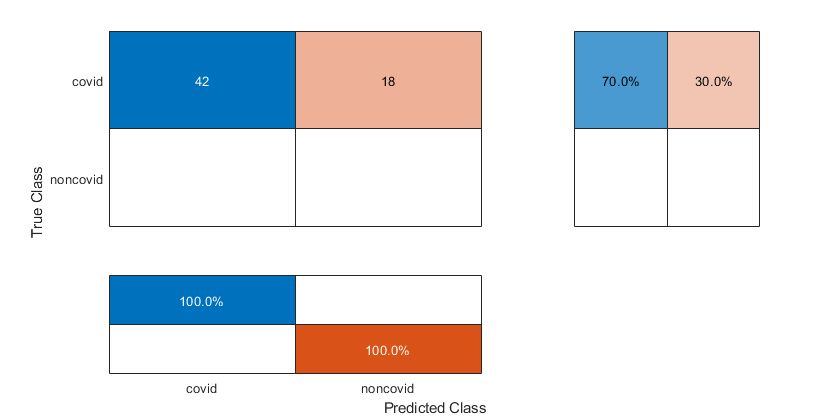

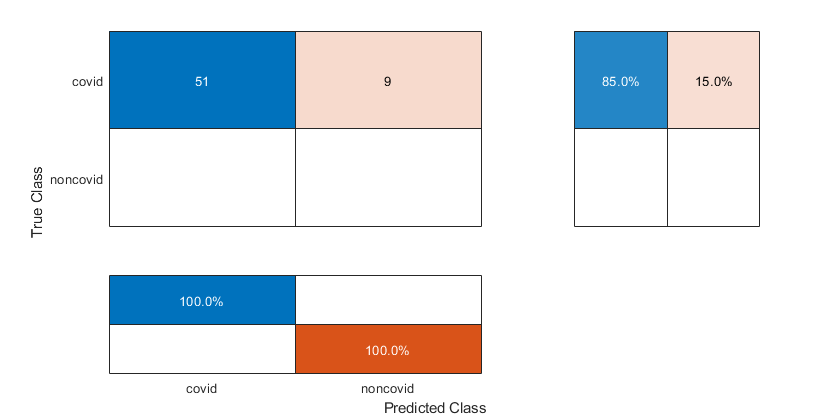

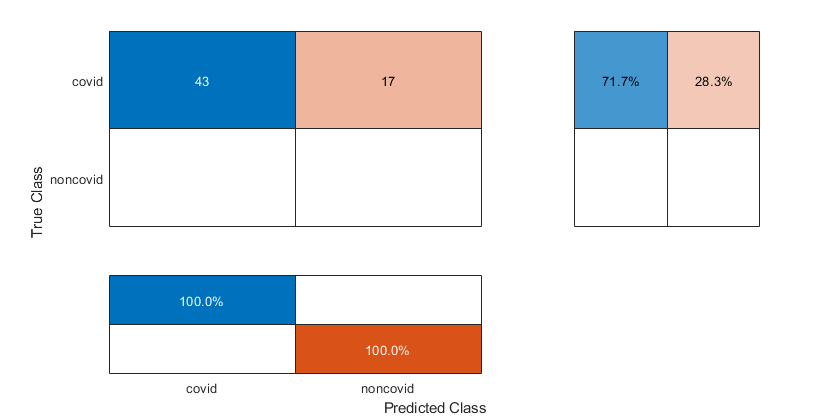

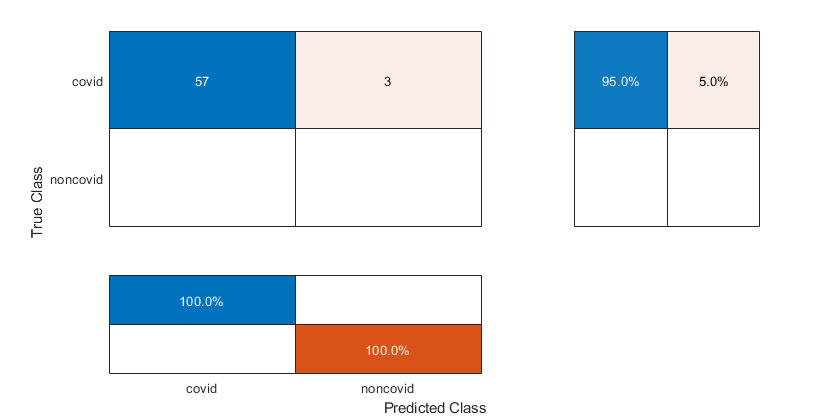


% Extract the class labels from the test data.
YTest = imdsTest.Labels;

accuracy = mean(YPred == YTest);

% Calculate Average F-score.
s = max(size(unique(YTest)));
conf_values = confusionmat(YTest, YPred);
tp_m = diag(conf_values); 
for i = 1:s
   % Get true positive, false negative, false positive
    TP = conf_values(1,1);
    sumTP = sumTP + TP;
    FN = conf_values(1,2);
    sumFN = sumFN + FN;
    FP = conf_values(2,1);
    sumFP = sumFP + FP;
    TN = conf_values(2,2);
    sumTN = sumTN + TN;
    
    % Calculate Recall, precision, fscore
    Recall = TP /(TP + FN);
    if isnan(Recall)
        Recall = 0;
    end
    % Calculate Precision
    Precision = TP / (TP + FP);
    if isnan(Precision)
        Precision = 0;
    end
    % Calculate FScore
    FScore = (2*(Precision * Recall)) / (Precision+Recall);
    if isnan(FScore)
        FScore = 0;
    end
end

% Display confusion chart.
fig = figure;
conf = confusionchart(YTest, YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');

combined_mat =     49    11
     0     0


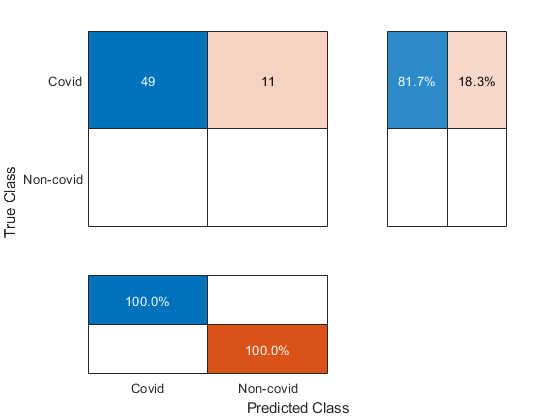

avg_ACC = 0.8133

avg_FScore = 0.8941

stdDev_ACC = 0.1043

stdDev_FScore = 0.0635

fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;
ACC_array = [ACC_array accuracy];
FScore_array = [FScore_array FScore];

end

sumTP = round(sumTP/5);
sumFN = round(sumFN/5);
sumFP = round(sumFP/5);
sumTN = round(sumTN/5);

combined_mat = [sumTP, sumFN ; sumFP, sumTN];


% Display avg confusion chart.
figure;
conf = confusionchart(combined_mat,["Covid", "Non-covid"],'RowSummary','row-normalized','ColumnSummary','column-normalized');

avg_ACC = mean(ACC_array)
avg_FScore = mean(FScore_array)

stdDev_ACC = std(ACC_array)
stdDev_FScore = std(FScore_array)

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels. With Actiavation Heatmaps

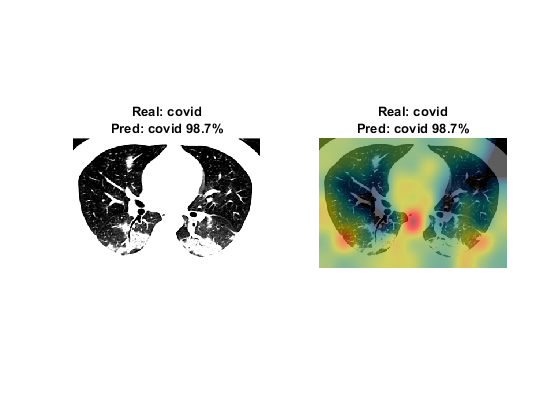

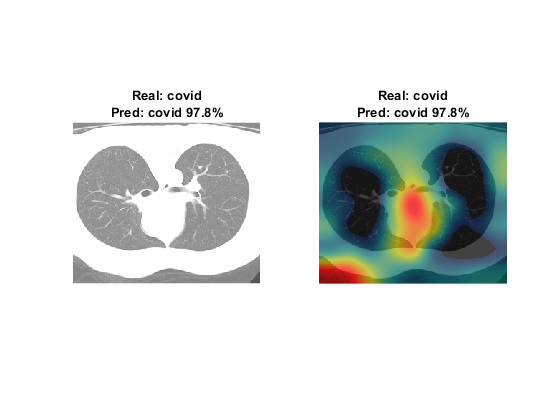

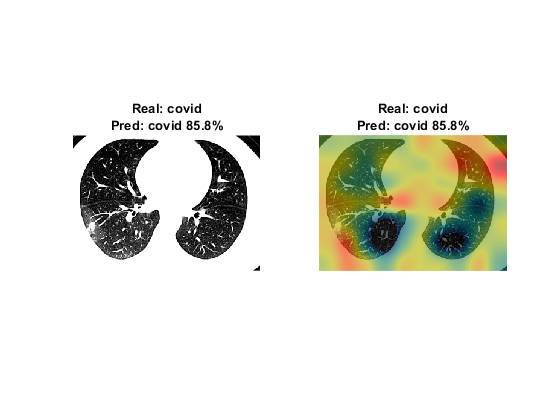

idx = randperm(numel(imdsTest.Files),3);
figure
for i = 1:3 
    I = readimage(imdsTest,idx(i));
    actlabel = YTest(idx(i));
    predlabel = YPred(idx(i));
    
    layerName = 'activation_49_relu';
    
    %Compute the activations of the resized image
    % in the ReLU layer that follows the last convolutional layer of the network
    imResized = imresize(I,[inputSize(1), NaN]);
    imageActivations = activations(net,imResized,layerName);
    
    %global average pooling (get average of activations)
    scores = squeeze(mean(imageActivations,[1 2]));
    fcWeights = net.Layers(end-2).Weights;
    fcBias = net.Layers(end-2).Bias;
    
    %get predicted class/classes with highes scores for CAM
    scores =  fcWeights*scores + fcBias;
    [~,classIds] = maxk(scores,2);
    weightVector = shiftdim(fcWeights(classIds(1),:),-1);
    classActivationMap = sum(imageActivations.*weightVector,3);
    
    %get the top class labels and the final normalized class scores
    scores = exp(scores)/sum(exp(scores));     
    maxScores = scores(classIds);
    labels = class(classIds);
    
    %Plot the class activation map
    figure;
    subplot(1,2,1)
    imshow(imResized)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});
    
    subplot(1,2,2)
    CAMshow(imResized,classActivationMap)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});

end


drawnow




HELPER FUNCTIONS FOR CAM

function CAMshow(im,CAM)
    imSize = size(im);
    CAM = imresize(CAM,imSize(1:2));
    CAM = normalizeImage(CAM);
    CAM(CAM<0.2) = 0;
    cmap = jet(255).*linspace(0,1,255)';
    CAM = ind2rgb(uint8(CAM*255),cmap)*255;
    
    combinedImage = double(rgb2gray(im))/2 + CAM;
    combinedImage = normalizeImage(combinedImage)*255;
    imshow(uint8(combinedImage));
end


function N = normalizeImage(I)
    minimum = min(I(:));
    maximum = max(I(:));
    N = (I-minimum)/(maximum-minimum);
end